`EE 150`

`Signals and Systems`

` Lab 2 System Analysis in Time Domain`

`Date Performed: 20220329`

`Class Id: Tue`

`Name & ID: LiuYifei 2020533131`

`1. `$y^{\prime \prime } \left(t\right)+3y^{\prime } \left(t\right)+6y\left(t\right)=6f^{\prime } \left(t\right)-8f\left(t\right),f\left(t\right)=e^{-t} u\left(t\right),y\left(0_- \right)=0,y^{\prime } \left(0_- \right)=10,y\left(0_+ \right)=0,y^{\prime } \left(0_+ \right)=6$`. Find out the zero-input response and plot it.`

clear;syms y(t) 
dddy=diff(y,t,3);
ddy=diff(y,t,2);
dy=diff(y,t,1);
eqn=(ddy+3*dy+6*y==0);
conds = [y(0)==0, dy(0)==10]; 
ysol = dsolve(eqn, conds); 
yzi = simplify(ysol)

$$yzi = \frac{4\,\sqrt{15}\,{\mathrm{e}}^{-\frac{3\,t}{2}}\,\sin\left(\frac{\sqrt{15}\,t}{2}\right)}{3}$$

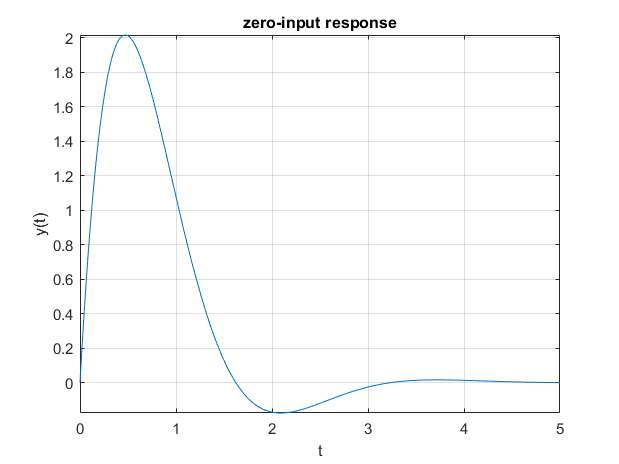

fplot(t,yzi,[0 5])
xlabel("t");ylabel("y(t)");title("zero-input response");grid on;

`2. `$y^{\prime \prime \prime } \left(t\right)+6y^{\prime \prime } \left(t\right)+11y^{\prime } \left(t\right)+6y\left(t\right)=f^{\prime \prime } \left(t\right)+2f\left(t\right)$`, find the impulse response, the step response and the relationship of the two response. Plot them in a 3*1 subplot.`

`    a. Find the impulse response. Plot it in the first position of a 3*1 subplot.`

`    b. Find the step response. Plot it in the second position of the 3*1 subplot.`

`    c. What is the relationship between impulse response and step response? Try to change a to b, or b to a. Plot the result in the third position of the 3*1 subplot.`

(A)

subplot(311);
t=-5:0.1:5;
sys=tf([1,0,2],[1 6 11 6]);
h=impulse(sys,t);
h=transpose(h);
tt=-5:10/length(h):5;
tt=tt(1:end-1);
plot(tt,h)
title("impulse response");grid on;

(B)

subplot(312);
h2=step(sys,t);
h2=transpose(h2);
tt=-5:10/length(h2):5;
tt=tt(1:end-1);
plot(tt,h2)
title("step response");grid on;

(C)

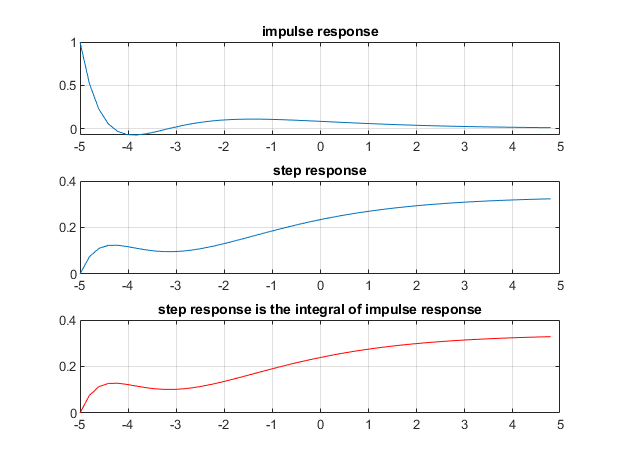

subplot(313);
jifen=cumtrapz(h*0.1);
plot(tt,jifen,"Color","r")
title("step response is the integral of impulse response");grid on;

`3. `$y^{\prime \prime } \left(t\right)+4y^{\prime } \left(t\right)+4y\left(t\right)=f^{\prime } \left(t\right)+3f\left(t\right)$`, where `$f\left(t\right)=e^{-t} u\left(t\right),y\left(0_+ \right)=0,y^{\prime } \left(0_+ \right)=1$`. Find out the zero-state response by solving differential equation, using function lsim and convolution. Compare the three results by plotting their result in a 3*1 subplot.`

clear;clf;

#### `solving differential equation`

syms y(t) f(t);
dddy=diff(y,t,3);
ddy=diff(y,t,2);
dy=diff(y,t,1);

dddf=diff(f,t,3);
ddf=diff(f,t,2);
df=diff(f,t,1);
eqn=ddy+4*dy+4*y==3*exp(-t)*heaviside(t)-exp(-t)*heaviside(t)

$$eqn(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+4\,\frac{\partial }{\partial t}y\left(t\right)+4\,y\left(t\right)=2\,{\mathrm{e}}^{-t}\,\mathrm{heaviside}\left(t\right)$$

subplot(311);
cons=[y(0)==0,dy(0)==1];
res=dsolve(eqn,cons);
yzi = simplify(res)

$$yzi = -{\mathrm{e}}^{-2\,t}\,\left(\mathrm{sign}\left(t\right)-{\mathrm{e}}^{t}-{\mathrm{e}}^{t}\,\mathrm{sign}\left(t\right)+t\,\mathrm{sign}\left(t\right)+1\right)$$

fplot(t,yzi,[0 5])
xlabel("t");ylabel("y(t)");title("differential equation");grid on;
ylim([0 0.4])

#### `using function lsim`

clear;
subplot(312)
t = 0:0.01:5;
sys = tf([1 3],[1 4 4]);
f = exp(-t);
y=lsim(sys,f,t);
plot(t,y)
xlabel("t");ylabel("y(t)");title("lsim");grid on;

#### `convolution`

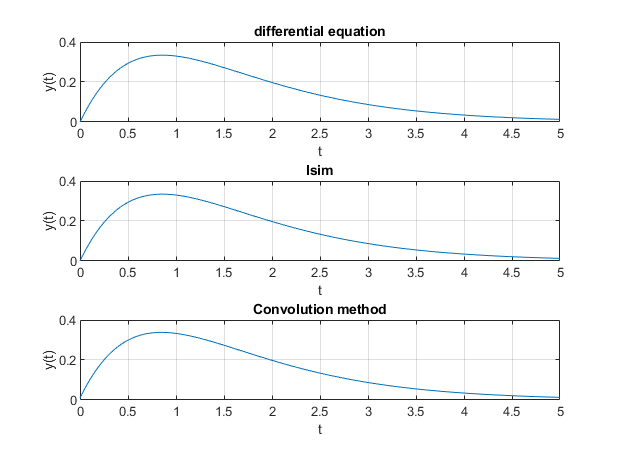

subplot(313)
h = impulse(sys,t);
f = exp(-t);
y = conv(h,f)*.01;
n = length(y);
tt = (0:n-1)*.01;
plot(tt,y);xlabel('t');ylabel('y(t)');title('Convolution method'),grid on;xlim([0 5]);

`4. For the following circuit, `$R=1\Omega ,C=1F,f\left(t\right)=\left(1+e^{-3t} \right)u\left(t\right),\;u_c \left(0_- \right)=1$`.  `

        Tips: the circuit can be describe as: $R\cdot C\frac{du_c \left(t\right)}{\textrm{dt}}+u_c \left(t\right)=f\left(t\right)$

      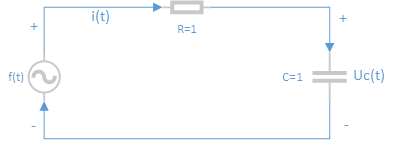

`    a. Follow the tips, complete the differential equation describing the system in text.`

`    b. Find out `$u_c \left(t\right)$ and p`lot the result. `

#### (A)

clear;clf;
syms f(t) u(t)
du=diff(u,t,1);
eqn=(du+u==f)

$$eqn(t) = \frac{\partial }{\partial t}u\left(t\right)+u\left(t\right)=f\left(t\right)$$

#### (B)

conds=(u(0)==1);%由于等式右边只有f(t)，可以预见uc0+=uc0-
eqn=(du+u==1+exp(-3*t));
uc=simplify(dsolve([eqn],conds))

$$uc = \frac{{\mathrm{e}}^{-t}}{2}-\frac{{\mathrm{e}}^{-3\,t}}{2}+1$$

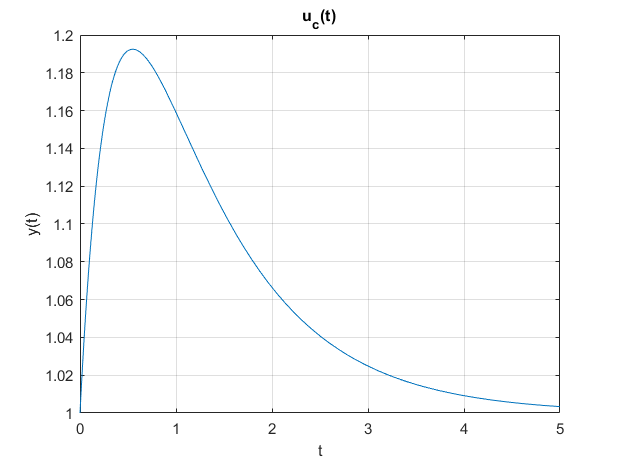

fplot(t,uc,[0 5])
ylim([1 1.2])
xlabel("t");ylabel("y(t)");title("u_c(t)");grid on;

5.` Please implement the convolution function of the discrete sequence by yourself (do not use function conv). Use the your student ID as the inputs and display the convolution result.`

SID=[2 0 2 0 5 3 3 1 3 1]

SID =      2     0     2     0     5     3     3     1     3     1



SIDR=flip(SID);
result=1:2*length(SID)-1;
len=length(SID)

len = 10

for i = 1:len
    result(i)=sum(SID(1:i).*(SIDR(end-i+1:end)));
end
for i = 1:len-1
    result(i+len)=sum(SID((1+i):end).*(SIDR(1:end-i)));
end
result

result =      4     0     8     0    24    12    32    16    49    38    51    32    45    34    25    12    11     6     1


%验证算法正确性
conv(SID,SID)-result

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
